%Import data
fileLoc = "Optimisations789"

fileLoc = "Optimisations789"

names = dir(fileLoc);
names = string({names(:).name});
namesInd = endsWith(names, ".mat");
names = names(namesInd)

names = 1×3 string array
    "Optimisation7.mat"    "Optimisation8.mat"    "Optimisation9.mat"



allData = []


allData =

     []



indexs = [];

for i = 1:length(names)

data = load(fileLoc + "\" + names(i));
data = data.data;

RsCrit2 = cell2mat(data{3,2}.RsCrit2);
Maximisepeaknumber = cell2mat(data{3,2}.Maximisepeaknumber);
Minimisemethodtime = cell2mat(data{3,2}.Minimisemethodtime);
GradTime = data{2,2}.GradTime;
InitalOM = data{2,2}.InitalOM;
IsoHoldTime = data{2,2}.IsoHoldTime;

RsCrit2 = exp(-RsCrit2);
Maximisepeaknumber = round(exp(-Maximisepeaknumber),1);
Minimisemethodtime = exp(Minimisemethodtime);

index = (Maximisepeaknumber >= 11) & (RsCrit2 >= 1.5);
%index = (Maximisepeaknumber == 11);

RsCrit2 = RsCrit2(index);
Maximisepeaknumber = Maximisepeaknumber(index);
Minimisemethodtime = Minimisemethodtime(index);
GradTime = GradTime(index);
InitalOM = InitalOM(index);
IsoHoldTime = IsoHoldTime(index);

allData = [allData;
            RsCrit2 Maximisepeaknumber Minimisemethodtime (ones(length(RsCrit2), 1)*i)+21 GradTime InitalOM IsoHoldTime];

indexs = [indexs; index];
end

allData

allData =     1.5608   11.0000    8.6472   22.0000    9.3072   18.8005    1.6755
    1.6431   11.0000    6.6327   22.0000    9.5944   28.8408    0.2934
    1.5016   11.0000   10.8855   22.0000    9.8065   26.4248    4.3262
    1.5290   11.0000    8.0530   22.0000    8.0722   17.2705    1.5989
    1.5642   11.0000    7.8463   22.0000    9.8347    8.4688         0
    1.5835   11.0000    5.2589   22.0000    6.7900   32.4957    0.2718
    1.6001   11.0000    7.8750   22.0000    9.8499   17.0898    0.5218
    1.5420   11.0000    5.1915   22.0000    6.4911   27.0096         0
    1.6555   11.0000    5.5672   22.0000    8.0641   31.2580         0
    1.5849   11.0000    5.1806   22.0000    6.6602   31.3777    0.1719


allDataTab = array2table(allData, "VariableNames",["CritRes", "NumbPeaks", "MethTime", "ExpNumb", "GradTime", "OM", "IsoHoldTime"])

allDataTab = 13×7 table
    CritRes    NumbPeaks    MethTime    ExpNumb    GradTime      OM      IsoHoldTime
    _______    _________    ________    _______    ________    ______    ___________

    1.5608        11         8.6472       22        9.3072       18.8       1.6755  
    1.6431        11         6.6327       22        9.5944     28.841      0.29339  
    1.5016        11         10.886       22        9.8065     26.425       4.3262  
     1.529        11          8.053       22        8.0722     17.271       1.5989  
    1.5642        11         7.8463       22        9.8347     8.4688            0  
    1.5835        11         5.2589       22          6.79     32.496      0.27176  
    1.6001        11          7.875       22        9.849

indexs = logical(indexs)

indexs = 150×1 logical array
   0
   0
   0
   0
   0
   0
   0
   1
   1
   0


% Distance to pareto front using point to line cmtmdHPLC025,031,032

scatter(allData(:,1), allData(:,3), 15,'filled')
xlabel("RsCrit2")
ylabel("Minimisemethodtime")

equation = polyfit([1.6555, 1.61603, 1.58488, 1.54195 ], [5.56718, 5.36548, 5.18061, 5.19155],1)

equation =     3.4639   -0.2146


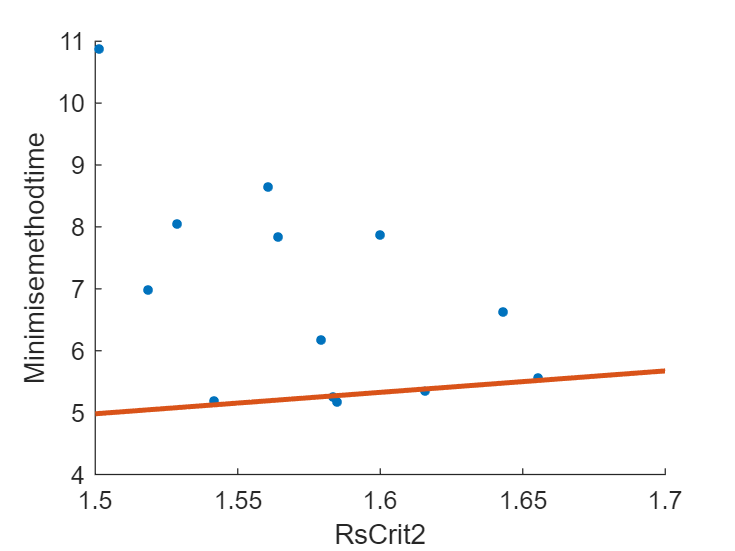

hold on 
fplot(poly2sym(equation), [1.5 1.7], "LineWidth",2)
hold off


allDist = zeros(length(allData(:,1)),3);
for i = 1:length(allData(:,1))
    allDist(i,:) = findMinDist([allData(i,1), allData(i,3)], poly2sym(equation), [1.5 2.19], 0.1, 1.5, 12.5);
end

allDist(:,1) = normalize(allDist(:,1), 1, "range", [0 1])

allDist =     0.5733    1.7000    5.6740
    0.1748    1.7000    5.6740
    1.0000    1.8000    6.0204
    0.4947    1.7000    5.6740
    0.4339    1.7000    5.6740
    0.0028    1.6000    5.3276
    0.4158    1.7000    5.6740
    0.0505    1.5000    4.9812
    0.0464    1.7000    5.6740
    0.0103    1.6000    5.3276



allDistances = ones(length(indexs),1)

allDistances =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


allDistances(indexs,1) = allDist(:,1);

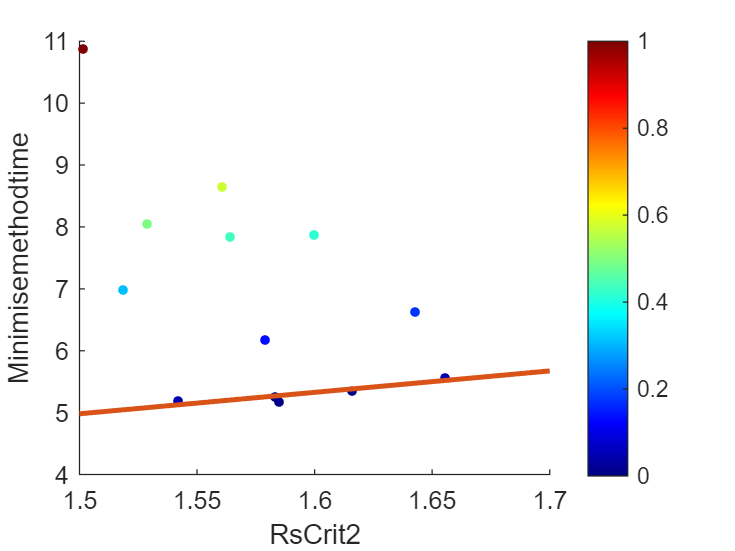


scatter(allData(:,1), allData(:,3), 15,allDist(:,1),'filled')
xlabel("RsCrit2")
ylabel("Minimisemethodtime")
hold on 
fplot(poly2sym(equation), [1.5 1.7], "LineWidth",2)
% for i = 1:length(allDist(:,1))
%     plot([allDist(i,2) allData(i,1)], [allDist(i,3) allData(i,3)], "b-" )
% end

hold off
colormap(jet)
colorbar
caxis([0 1])

function distance=point_to_line_distance(pt, v1, v2)
%Calculate distance between a point and a line in 2D or 3D.
% syntax:
% distance = point_to_line(pt, v1, v2)
% pt is a nx3 matrix with xyz coordinates for n points
% v1 and v2 are vertices on the line (each 1x3)
% d is a nx1 vector with the orthogonal distances
%
% 2D inputs are extended to 3D by setting all z-values to 0, all inputs should be either nx2 or nx3
% (1x2 or 1x3 for v1 and v2).
%
% The actual calculation is a slightly edit version of this line (which only works for 3D points):
% distance=norm(cross(v1-v2,pt-v2))/norm(v1-v2)
%
%  _______________________________________________________________________
% | Compatibility | Windows 10  | Ubuntu 20.04 LTS | MacOS 10.15 Catalina |
% |---------------|-------------|------------------|----------------------|
% | ML R2020a     |  works      |  not tested      |  not tested          |
% | ML R2018a     |  works      |  works           |  not tested          |
% | ML R2015a     |  works      |  works           |  not tested          |
% | ML R2011a     |  works      |  works           |  not tested          |
% | ML 6.5 (R13)  |  works      |  not tested      |  not tested          |
% | Octave 5.2.0  |  works      |  works           |  not tested          |
% | Octave 4.4.1  |  works      |  not tested      |  works               |
% """""""""""""""""""""""""""""""""""""""""""""""""""""""""""""""""""""""""
%
% Version: 1.3.2
% Date:    2020-06-28
% Author:  H.J. Wisselink
% Licence: CC by-nc-sa 4.0 ( creativecommons.org/licenses/by-nc-sa/4.0 )
% Email=  'h_j_wisselink*alumnus_utwente_nl';
% Real_email = regexprep(Email,{'*','_'},{'@','.'})
%check inputs
if nargin~=3
    error('HJW:point_to_line_distance:nargin',...
        'Incorrect number of inputs, expected 3.');
end
if ~isnumeric(pt) || ~any(size(pt,2)==[2 3]) || any(size(pt)==0)
    error('HJW:point_to_line_distance:pt_type_size',...
        'First input (pt) is not numeric or has an incorrect shape.')
end
if ~isnumeric(v1) || numel(v1)~=size(pt,2)
    error('HJW:point_to_line_distance:v_type_size',...
        ['Second input (v1) is not numeric or has an incorrect size.',char(10),...
        'Expected 1x3 or 1x2, which should match the first input.']) %#ok<CHARTEN>
end
if ~isnumeric(v2) || numel(v2)~=size(pt,2)
    error('HJW:point_to_line_distance:v_type_size',...
        ['Third input (v2) is not numeric or has an incorrect size.',char(10),...
        'Expected 1x3 or 1x2, which should match the first input.']) %#ok<CHARTEN>
end
%prepare inputs
v1=v1(:)';%force 1x3 or 1x2
v2=v2(:)';%force 1x3 or 1x2
if length(v1)==2,v1(3)=0;  end%extend 1x2 to 1x3 if needed
if length(v2)==2,v2(3)=0;  end%extend 1x2 to 1x3 if needed
if size(pt,2)==2,pt(1,3)=0;end%extend nx2 to nx3 if needed
v1_ = repmat(v1,size(pt,1),1);
v2_ = repmat(v2,size(pt,1),1);
%actual calculation
a = v1_ - v2_;
b = pt - v2_;
distance = sqrt(sum(cross(a,b,2).^2,2)) ./ sqrt(sum(a.^2,2));
%this is equivalent to the following line for a single point
%distance=norm(cross(v1-v2,pt-v2))/norm(v1-v2)
end

function output = findMinDist(point, line, xlims, dx, normAxisX, normAxisY)

xCords = xlims(1):dx:xlims(2);
pointsDist = zeros(1, length(xCords));

for i = 1:length(pointsDist)
    x = xCords(i);
    y = double(subs(line, x));
    pointsDist(i)= sqrt((((y-point(2))/(normAxisY)) ^2) + (((x-point(1))/(normAxisX)) ^2));
end

[minDist, ind] = min(pointsDist);
xMin = xCords(ind);
yMin = double(subs(line, xMin));
output = [minDist, xMin, yMin];

end

function [groups, resultOfGroup, expNumb] = groupByClose(data, arrayDiff, results)
groups = cell(length(data(:,1)),1);
resultOfGroup = cell(length(data(:,1)),1);
expNumb = cell(length(data(:,1)),1);
    for i = 1:length(data(:,1))
        allowed = ((data(i,:) + arrayDiff) >= data) & ((data(i,:) - arrayDiff) <= data);
        allClose = sum(allowed, 2) == length(arrayDiff);
        groups{i,1} = data(allClose,:);
        resultOfGroup{i, 1} = results(allClose,:);
        expNumb{i,1} = find(allClose)';
    end
end
